format long eng;
kbr1b_x = importdata("KBR1B_2020-09-28_Y_04.txt");
gni1b_a = importdata("GNI1B_2020-09-28_C_04.txt");
gni1b_b = importdata("GNI1B_2020-09-28_D_04.txt");
sca1b_a = importdata("SCA1B_2020-09-28_C_04.txt");
sca1b_b = importdata("SCA1B_2020-09-28_D_04.txt");
acc1b_a = importdata("ACT1B_2020-09-28_C_04.txt");
acc1b_b = importdata("ACT1B_2020-09-28_D_04.txt");

los = gni1b_b.data(:, 1: 3) - gni1b_a.data(:, 1: 3);
dis = sqrt(sum(los.^2, 2));
los = los ./ dis;
rotm_a = zeros(17280, 3, 3);
rotm_b = zeros(17280, 3, 3);
eqa = zeros(17280, 6);
eqb = kbr1b_x(:, 2) - dis(1: 5: end);
eul = zeros(86400, 6);
for i = 1: 86400
    % eul(i, 1: 3) = rotm2eul(transpose(irf2losf(gni1b_a.data(i, 1: 3), gni1b_b.data(i, 1: 3))) * (quat2rotm(sca1b_a.data(i, 2: 5))));
    % eul(i, 4: 6) = rotm2eul(transpose(irf2losf(gni1b_b.data(i, 1: 3), gni1b_a.data(i, 1: 3))) * (quat2rotm(sca1b_b.data(i, 2: 5))));
    rotm = irf2losf(gni1b_a.data(i, 1: 3), gni1b_b.data(i, 1: 3))' * quat2rotm(sca1b_a.data(i, 2: 5));
    eul(i, 1) = atan(rotm(3, 2) / rotm(3, 3));
    eul(i, 2) = -asin(rotm(3, 1));
    eul(i, 3) = atan(rotm(2, 1) / rotm(1, 1));
    rotm = irf2losf(gni1b_b.data(i, 1: 3), gni1b_a.data(i, 1: 3))' * quat2rotm(sca1b_b.data(i, 2: 5));
    eul(i, 4) = atan(rotm(3, 2) / rotm(3, 3));
    eul(i, 5) = -asin(rotm(3, 1));
    eul(i, 6) = atan(rotm(2, 1) / rotm(1, 1)); 
end

for i = 1: 17280
    eqa(i, 1: 3) = los(i*5-4, :) * (quat2rotm(sca1b_a.data(i*5-4, 2: 5)));
    eqa(i, 4: 6) = los(i*5-4, :) * (quat2rotm(sca1b_b.data(i*5-4, 2: 5)));
end
eqa(:, 1: 3) = -eqa(:, 1: 3);
diff_eqa = diff(eqa, 1);
% 10522: 11121
% 3695: 4284
% 3695: 4284
% 5972: 6571

diff2_eqa = diff(diff_eqa, 1);
diff3_eqa = diff(diff2_eqa, 1);
diff_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end));
diff2_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end), 2);
diff3_eqb = diff(diff2_eqb);
diff2_eqb = filter_pdfree(Num, diff2_eqb);
diff2_eqa = filter_pdfree(Num, diff2_eqa);
diff3_eqa = filter_pdfree(Num, diff3_eqa);
diff3_eqb = filter_pdfree(Num, diff3_eqb);
% fft_diff3_eqb = fft(diff3_eqb(10522: 11021));
% fft_diff3_eqa = [fft(diff3_eqa(10522: 11021, 4)), fft(diff3_eqa(10522: 11021, 5))];
% eqb = [fft_diff3_eqb(11); fft_diff3_eqb(21)];
% eqa = [fft_diff3_eqa(11, :); fft_diff3_eqa(21, :)];
% eqa_real = real(eqa);
% eqa_imag = imag(eqa);
% eqb_real = real(eqb);
% eqb_imag = imag(eqb);
% 
% eqa_abs = abs(eqa);
% eqa_ang = angle(eqa);
% eqb_abs = abs(eqb);
% eqb_ang = angle(eqb);
lsqr(diff3_eqa(5972: 6571, [2 3 5 6]), diff3_eqb(5972: 6571) - diff3_eqa(5972: 6571, [1 4])*[1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.99。


ans =     1.50863707357256e-003
   -49.3285068158284e-003
    29.5801634431948e-003
   -69.7031957455556e-006


lsqr(diff3_eqa(3695: 4284, [2 3 5 6]), diff3_eqb(3695: 4284) - diff3_eqa(3695: 4284, [1 4])*[1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.91。


ans =     2.53767379926829e-003
   -42.9343741974282e-003
   -121.843416815248e-006
    2.60168453687708e-003


lsqr(diff3_eqa(8256: 8855, [2 3 5 6]), diff3_eqb(8256: 8855) - diff3_eqa(8256: 8855, [1 4])*[1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.87。


ans =    -21.9154053225179e-003
    5.06284700213425e-003
   -1.40792962023656e-003
   -30.9331103111578e-003


lsqr(diff3_eqa(10522: 11121, [2 3 5 6]), diff3_eqb(10522: 11121) - diff3_eqa(10522: 11121, [1 4])*[1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.85。


ans =    -4.54544194245089e-003
    51.9152066632049e-003
    1.68384812115479e-003
    71.0313316978716e-003


solver_spectral(diff2_eqa(3695: 4284, :), diff2_eqb(3695: 4284), [4 6], 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.011。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.011。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.011。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.012。


FFT_model_mat_at_freq_signal =     9.56830277166639e-006    276.477159496859e-006
    4.83445362915759e-006    208.778302923391e-009


lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。


FFT_data_vec_at_freq_signal =     14.6151915944997e-006
    6.80887651880574e-006


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.9e-09。


ans =     2.88834851192299e-003


solver_spectral(diff3_eqa(3695: 4284, :), diff3_eqb(3695: 4284), [4 6], 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.036。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.036。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.036。


FFT_model_mat_at_freq_signal =     1.20144284385562e-006    34.7136039144422e-006
    1.21143429224506e-006    61.9496430266012e-009


lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.031。


FFT_data_vec_at_freq_signal =     1.83416404417547e-006
    1.70725089024211e-006


lsqr 在解的 迭代 2 处收敛，并且相对残差为 9.9e-11。


ans =     2.85999050667981e-003


solver_spectral(diff3_eqa(5972: 6571, :), diff3_eqb(5972: 6571), [4 6], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.029。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.029。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.029。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.036。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.036。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.036。


FFT_model_mat_at_freq_signal =     1.22790071690106e-006    34.7339233279516e-006
    1.21395434219676e-006    52.2021041114816e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.026。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.026。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.026。


FFT_data_vec_at_freq_signal =     1.78202164430991e-006
    1.70308145000789e-006


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.1e-10。


ans =     257.183993309256e-006


solver_spectral(diff3_eqa(8256: 8855, :), diff3_eqb(8256: 8855), [4 5], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.041。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.041。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.041。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.049。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.049。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.049。


FFT_model_mat_at_freq_signal =     1.22386802451173e-006    34.7121653284739e-006
    1.20273296042772e-006    344.579951036603e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.058。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.058。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.058。


FFT_data_vec_at_freq_signal =     1.81744764842294e-006
    1.77598074046623e-006


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1e-10。


ans =     1.44566668639463e-003


solver_spectral(diff3_eqa(10522: 11121, :), diff3_eqb(10522: 11121), [4 5], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。


FFT_model_mat_at_freq_signal =     1.20046808284400e-006    34.7836084538916e-006
    1.21909984444849e-006    309.600666853162e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.06。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.06。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.06。


FFT_data_vec_at_freq_signal =     1.79970037969674e-006
    1.80435376754416e-006


lsqr 在解的 迭代 2 处收敛，并且相对残差为 2e-10。


ans =     1.90389873315727e-003


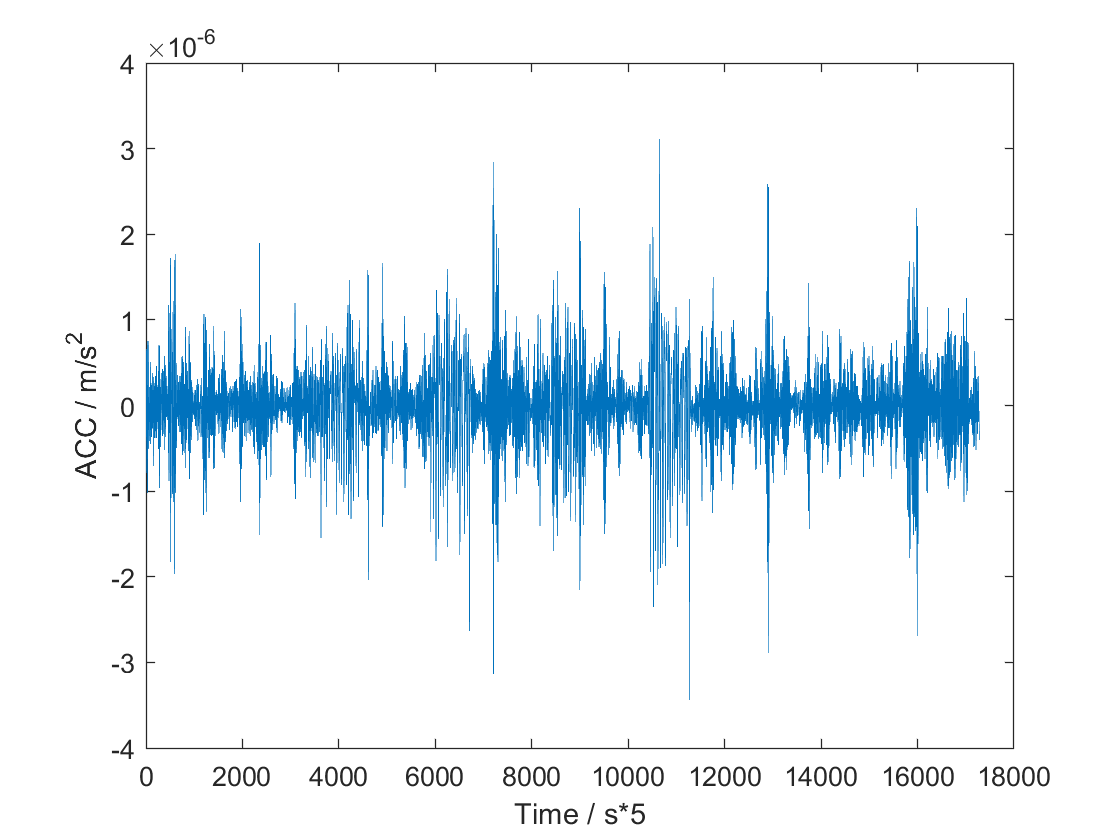

acc_grav = importdata("..//..//temp//acc_grav_calibra2.txt");
acc_grav = acc_grav(86401: end, :);
%vel_grac = cumtrapz(acc_grav, 1);
acc_grav_rela = [acc_grav(:, 1) - acc_grav(:, 4), acc_grav(:, 2) - acc_grav(:, 5), acc_grav(:, 3) - acc_grav(:, 6)];
%vel_grav_rela = [vel_grav(:, 1) - vel_grav(:, 4), vel_grav(:, 2) - vel_grav(:, 5), vel_grav(:, 3) - vel_grav(:, 6)];
gnv_a = importdata("GNV1B_2020-09-28_C_04.txt");
gnv_b = importdata("GNV1B_2020-09-28_D_04.txt");
gni_a = importdata("GNI1B_2020-09-28_C_04.txt");
gni_b = importdata("GNI1B_2020-09-28_D_04.txt");
kbr_x = importdata("KBR1B_2020-09-28_Y_04.txt");
acc_a = importdata("ACT1B_2020-09-28_C_04.txt");
acc_b = importdata("ACT1B_2020-09-28_D_04.txt");
acc_nongrav = [acc_a.data(:, 1) - mean(acc_a.data(:, 1)), acc_a.data(:, 2) - mean(acc_a.data(:, 2)), acc_a.data(:, 3) - mean(acc_a.data(:, 3)), acc_b.data(:, 1) - mean(acc_b.data(:, 1)), acc_b.data(:, 2) - mean(acc_b.data(:, 2)), acc_b.data(:, 3) - mean(acc_b.data(:, 3))];
acc_nongrav_gcrs = zeros(size(acc_nongrav));
for i = 1: length(acc_nongrav)
    rotm_a = quat2rotm(sca_c.data(i, 2: 5));
    rotm_b = quat2rotm(sca_d.data(i, 2: 5));
    acc_nongrav_gcrs(i, 1: 3) = rotm_a * acc_nongrav(i, 1: 3)';
    acc_nongrav_gcrs(i, 4: 6) = rotm_b * acc_nongrav(i, 4: 6)';
end
acc_nongrav_rela = [acc_nongrav_gcrs(:, 1) - acc_nongrav_gcrs(:, 4), acc_nongrav_gcrs(:, 2) - acc_nongrav_gcrs(:, 5), acc_nongrav_gcrs(:, 3) - acc_nongrav_gcrs(:, 6)];

range_acc = kbr_x(:, 4);

pos_rela = gnv_a.data(:, 1: 3) - gnv_b.data(:, 1: 3);
pos_rela_i = gni_a.data(:, 1: 3) - gni_b.data(:, 1: 3);
los = pos_rela ./ sqrt(sum(pos_rela.^2, 2));
los_i = pos_rela_i ./ sqrt(sum(pos_rela_i.^2, 2));
vel_rela = gni_a.data(:, 7: 9) - gni_b.data(:, 7: 9);
los_vec = vel_rela ./ sqrt(sum(pos_rela.^2, 2)) - pos_rela_i .* dot(los_i, vel_rela, 2) ./ sum(pos_rela.^2, 2);

range_acc_grav = zeros(length(los), 1);
for i = 1: length(range_acc_grav)
    range_acc_grav(i) = dot(acc_grav_rela(i, :), los(i, :)) + dot(vel_rela(i, :), los_vec(i, :)) + dot(acc_nongrav_rela(i, :), los_i(i, :));
end
range_acc_grav = range_acc_grav(1: 5: length(range_acc_grav));
range_acc_res = range_acc - range_acc_grav;
figure; plot(range_acc_res); xlabel("Time / s*5"); ylabel("ACC / m/s^2")

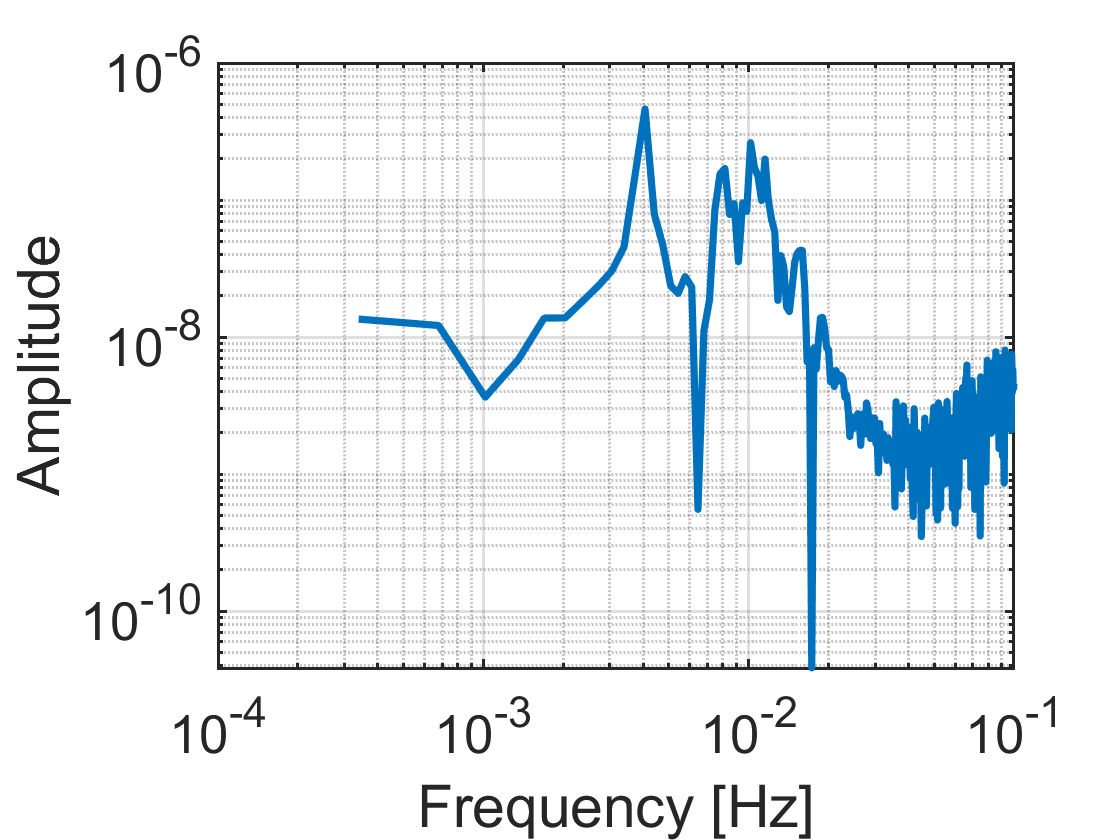

figure; fft_plot(range_acc_res(3695: 4284), 0.2)

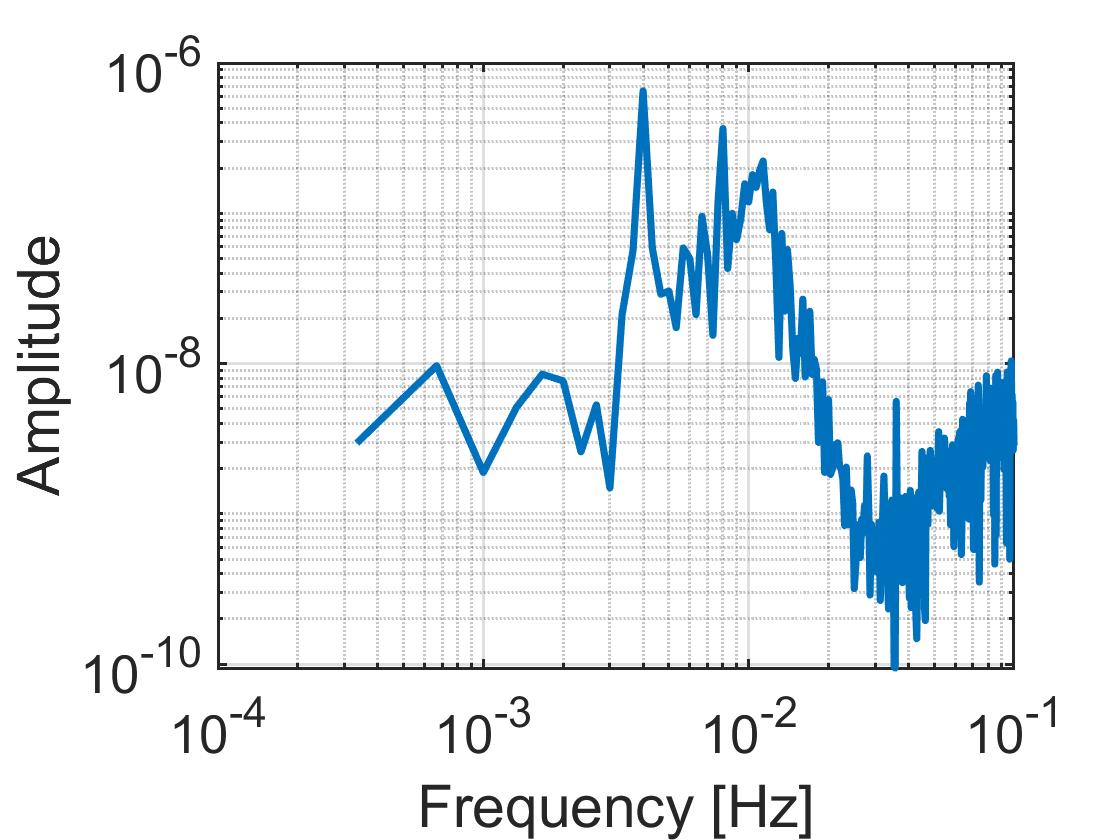

figure; fft_plot(range_acc_res(5972: 6571), 0.2)

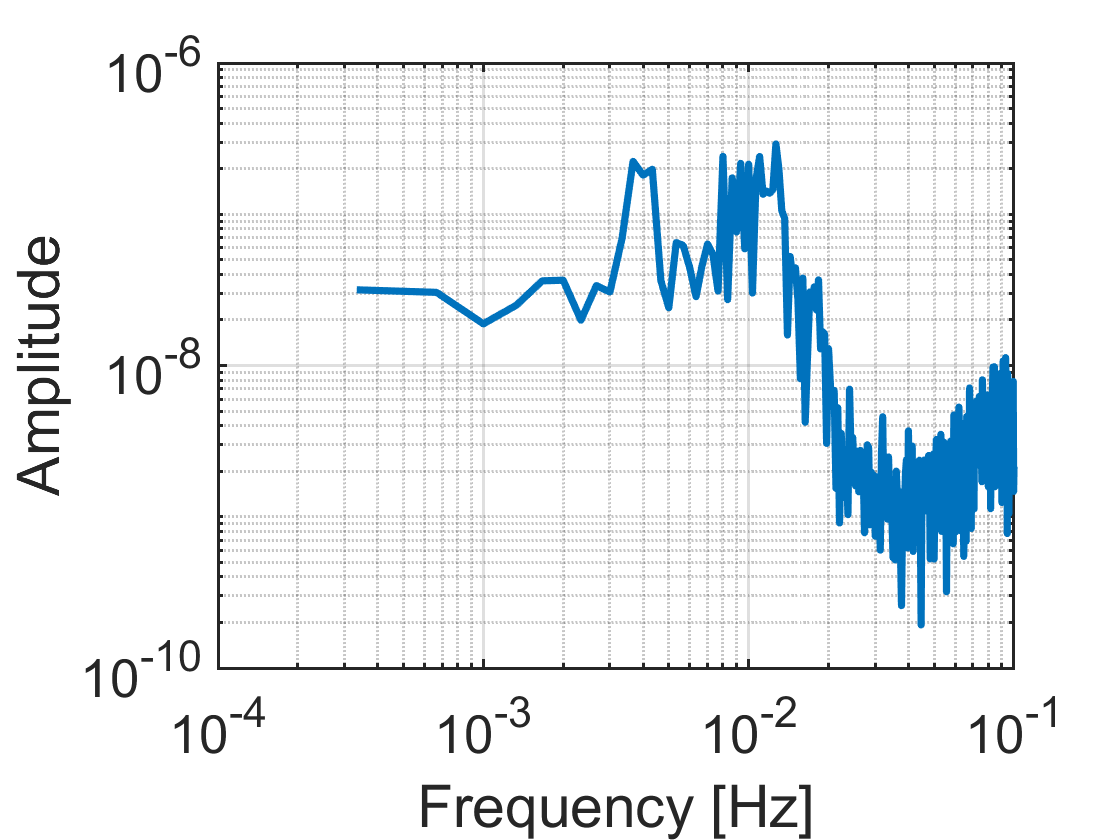

figure; fft_plot(range_acc_res(8256: 8855), 0.2)

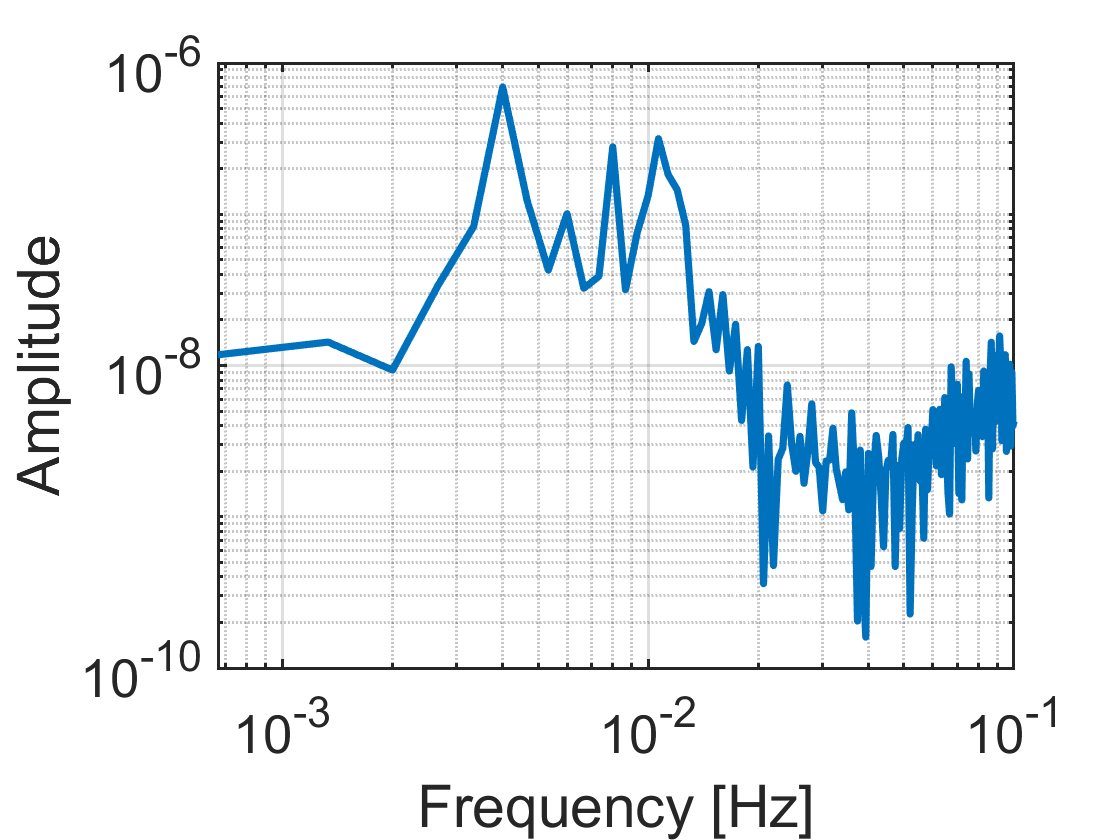

figure; fft_plot(range_acc_res(10822: 11121), 0.2)

a1 = spectral_component(filter_pdfree(Num, range_acc_res(3695: 4284)), 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.65。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.65。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.65。


a1 =     501.156538178400e-009
    244.706917804987e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(3695: 4284, 4)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。


a2 =     383.355521278336e-009
    194.417212791604e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(3695: 4284, 6)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.13。


a3 =     11.0727492099179e-006
    7.80180497160358e-009


-(a1(1) - 1.4444575 * a2(1)) / a3(1)

ans =     4.74897595001991e-003


a1 = spectral_component(filter_pdfree(Num, range_acc_res(5972: 6571)), 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.6。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.6。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.6。


a1 =     645.531044419000e-009
    384.209494541296e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(5972: 6571, 4)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


a2 =     391.568687634152e-009
    194.788555557654e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(5972: 6571, 6)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


a3 =     11.0795354313242e-006
    5.13848638787657e-009


(a1(1) - 1.4444575 * a2(1)) / a3(1)

ans =     7.21390506814228e-003


a1 = spectral_component(filter_pdfree(Num, range_acc_res(8256: 8855)), 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.93。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.93。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.93。


a1 =     189.547615092181e-009
    254.461788565783e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(8256: 8855, 4)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


a2 =     390.534249665271e-009
    193.019114059829e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(8256: 8855, 5)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


a3 =     11.0750035014035e-006
    54.0809089966261e-009


-(a1(1) - 1.4444575 * a2(1)) / a3(1)

ans =     33.8205320473465e-003


a1 = spectral_component(filter_pdfree(Num, range_acc_res(10522: 10821)), 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.48。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.48。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.48。


a1 =     1.28465007790780e-006
    270.465017201699e-009


a11 = spectral_component(filter_pdfree(Num, range_acc_res(10822: 11121)), 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.57。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.57。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.57。


a11 =     661.814275265652e-009
    284.030648506896e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10522: 10821, 4)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。


a2 =     381.297871580270e-009
    194.069140329639e-009


a22 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10822: 11121, 4)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.1。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.1。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.1。


a22 =     384.122259280228e-009
    196.833392341102e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10522: 10821, 5)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.13。


a3 =     11.0508576146193e-006
    49.8884980985996e-009


a33 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10822: 11121, 5)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.11。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.11。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.11。


a33 =     11.1215336692498e-006
    61.5751606363001e-009



(a1(1) - 1.4444575 * a2(1)) / a3(1)

ans =     66.4094618863595e-003


(a11(1) - 1.4444575 * a22(1)) / a33(1)

ans =     9.61791782612996e-003
